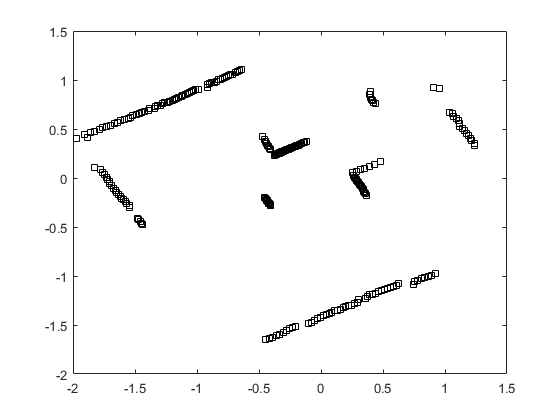

%set threshold for d and # of iterations
inliers = 5;
n = 50;
d = 0.005;
%iterate through RANSAC loop
plot(data(:,1), data(:,2), 'ks')

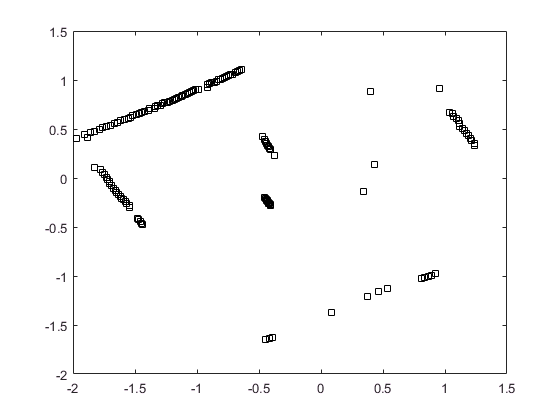

while size(data, 1) > 150
    for index = 1:30
        index1 = randi(length(data));
        index2 = randi(length(data));
        while norm(data(index2, :) - data(index1, :)) > .04
            index2 = randi(length(data));
        end
        
        %norm(data(index2, :) - data(index1, :))
        
        point1 = data(index1, :);
        %center the data around the randomly chosen point
        data2 = data - point1;
        %redefine points in new coordinate system
        point2 = data2(index2, :);
    
        vector = point2 / norm(point2);
        orthonormal = [-vector(2), vector(1)];
    
        distance = orthonormal * data2';
        new_inlier = length(find(abs(distance) < d));
        if new_inlier > inliers
            inliers = new_inlier;
            remove_idx = find(abs(distance) < d);
            line = vector;
            start_point = point1;
        end
    end
    lol = find(remove_idx > length(data) , 1) - 1;
    if isempty(lol)
        lol = length(remove_idx);
    end
    data(remove_idx(1:lol), :) = [];
end

figure
plot(data(:,1), data(:,2), 'ks');